## 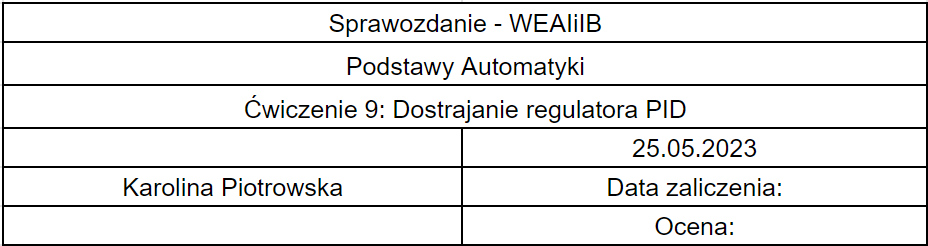

## Cel ćwiczenia

Zapoznanie z praktycznymi metodami doboru nastaw regulatora PID.

## Wstęp teoretyczny

W ćwiczeniu wykorzystywane są trzy metody:

- Zieglera-Nicolsa - nie wymaga znajomości modelu obiektu; trzeba przeprowadzić eksperyment

- Astroma-Hagglunda - bezpieczniejsza i szybsza

- Autotune - automatyczne dobranie nastawy w optymalny sposóbb.

## Przebieg laboratorium

### Klasyczny eksperyment Zieglera-Nicholsa

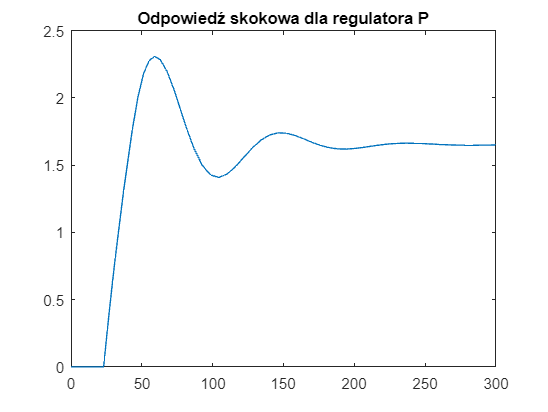

r = 2.5;
k = 1.18;
tau = 22;
T = 45;

kkr = 3.3;
Tosc = 75.781;
kp = 0.5 * kkr;
ki = 0;
kd = 0;

sim("dostrajanie.slx");
y = ans.y;
plot(y.time, y.signals.values)
title('Odpowiedź skokowa dla regulatora P')

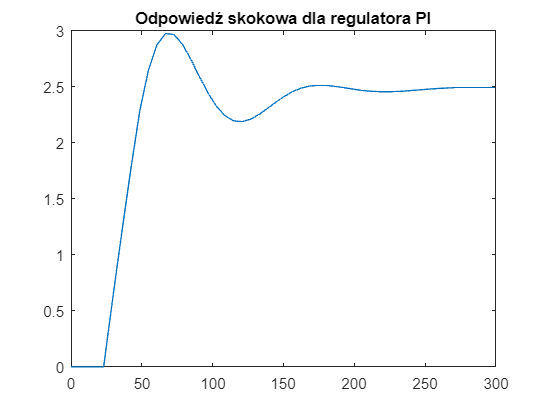

kp = 0.45 * kkr;
Ti = 0.85 * Tosc;
ki = kp / Ti;
kd = 0;

sim("dostrajanie.slx");
y = ans.y;
plot(y.time, y.signals.values)
title('Odpowiedź skokowa dla regulatora PI')

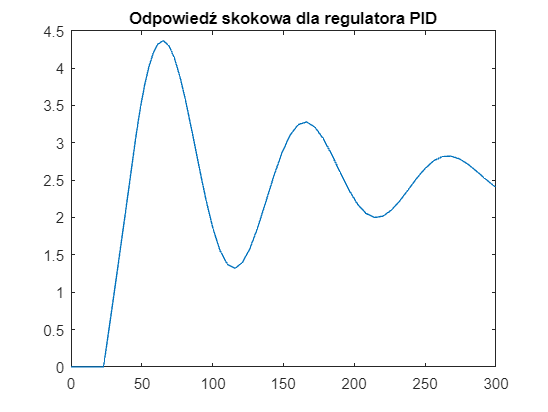

kp = 0.6 * kkr;
Ti = 0.5 * Tosc;
ki = kp / Ti;
Td = 0.12 * Tosc;
kd = kp / Td;

sim("dostrajanie.slx");
y = ans.y;
plot(y.time, y.signals.values)
title('Odpowiedź skokowa dla regulatora PID')

### Metoda Astroma-Hagglunda

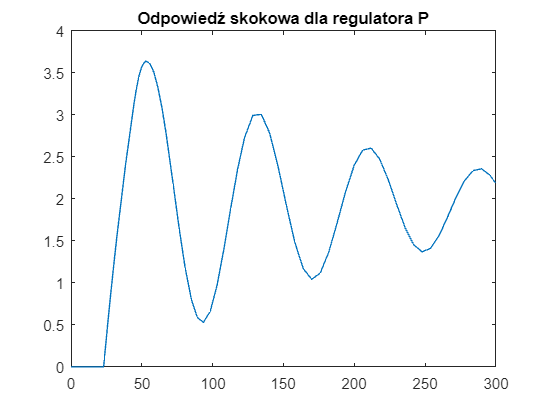

u0 = 1;
u1 = 5;
u = u1 - u0;
Tosc1 = 82.036;
A = 1.818 / 2;
kkryt1 = (4 * u) / (A * pi);
kp = 0.5 * kkryt1;
ki = 0;
kd = 0;

sim("dostrajanie.slx");
y = ans.y;
plot(y.time, y.signals.values)
title('Odpowiedź skokowa dla regulatora P')

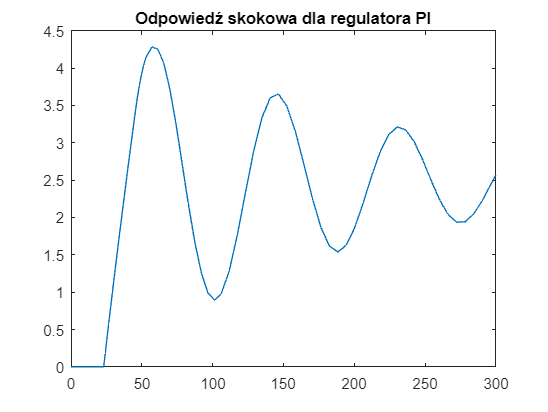

kp = 0.45 * kkryt1;
Ti = 0.85 * Tosc1;
ki = kp/Ti;
kd = 0;

sim("dostrajanie.slx");
y = ans.y;
plot(y.time, y.signals.values)
title('Odpowiedź skokowa dla regulatora PI')

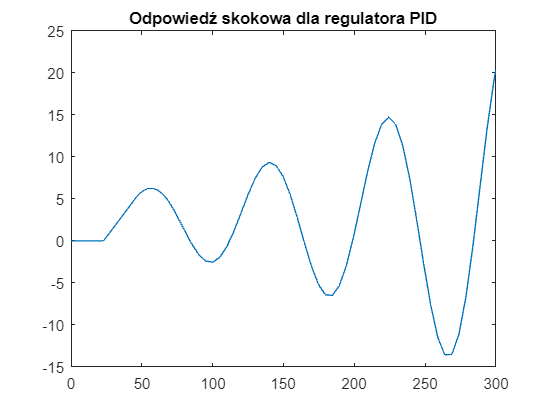

kp = 0.6 * kkryt1;
Ti = 0.5 * Tosc1;
ki = kp / Ti;
Td = 0.12 * Tosc1;
kd = kp / Td;

sim("dostrajanie.slx");
y = ans.y;
plot(y.time, y.signals.values)
title('Odpowiedź skokowa dla regulatora PID')

### Dostrajanie regulatora PID na podstawie parametrów transmitancji zastępczej

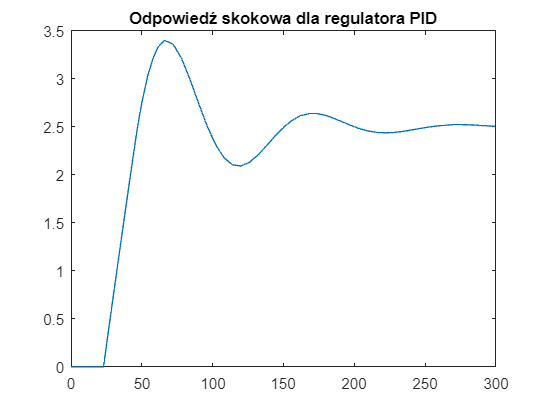

kp = (0.95 * 45) / (22 * 1.18);
Ti = 2.4 * 22;
ki = kp / Ti;
Td = 0.4 * 22;
kd = kp / Td;

sim("dostrajanie.slx");
y = ans.y;
plot(y.time, y.signals.values)
title('Odpowiedź skokowa dla regulatora PID')

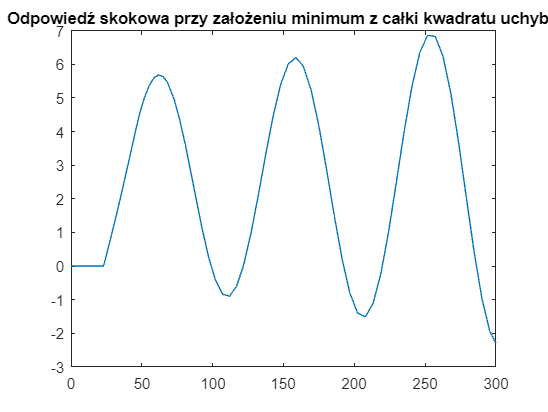

kp = (1.4 * 45) / (22 * 1.18);
Ti = 1.3 * 22;
ki = kp / Ti;
Td = 0.5 * 22;
kd = kp / Td;

sim("dostrajanie.slx");
y = ans.y;
plot(y.time, y.signals.values)
title('Odpowiedź skokowa przy założeniu minimum z całki kwadratu uchybu')

### Użycie funkcji „Autotune” dostępnej w środowisku SIMULINK

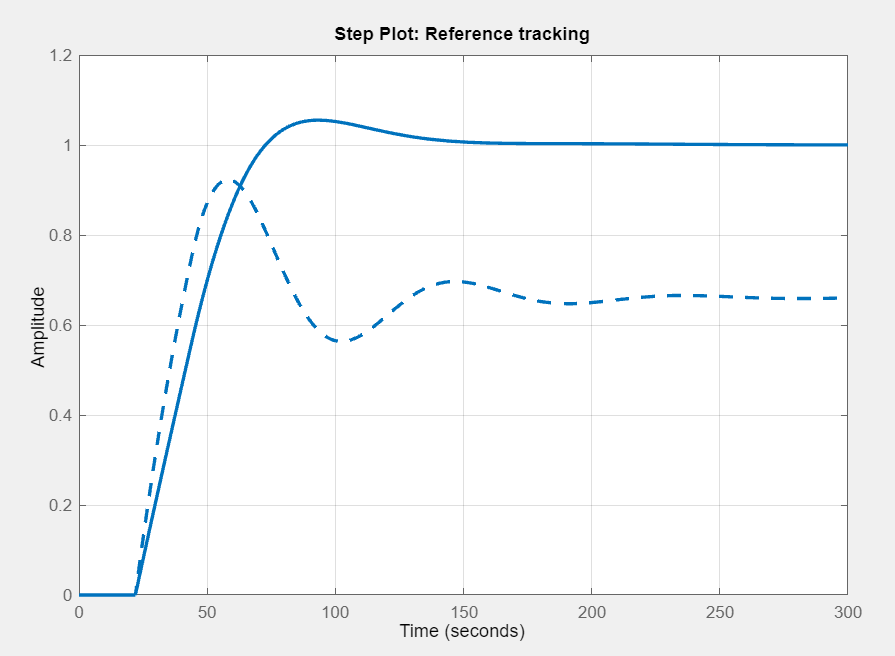

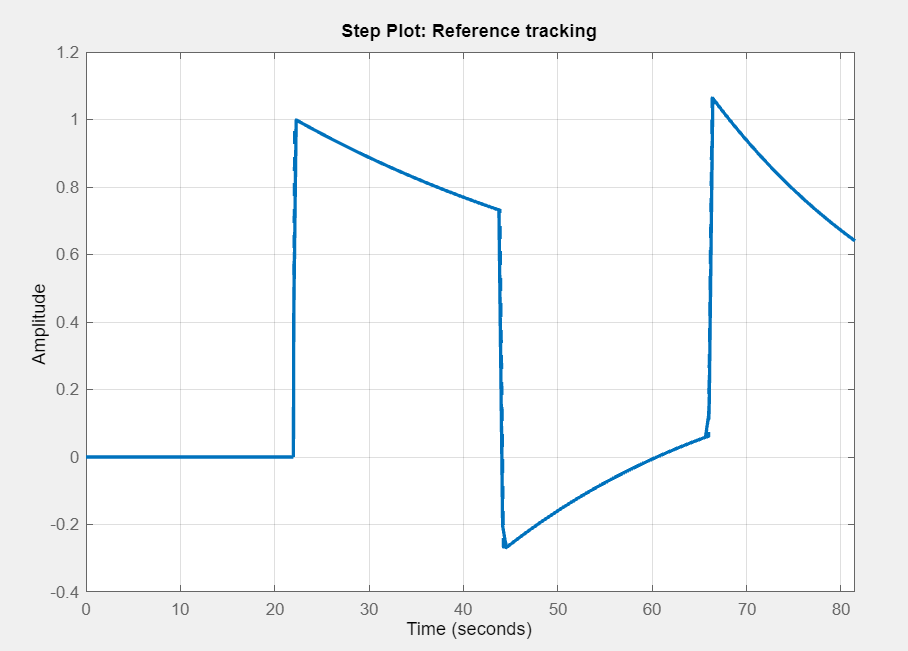

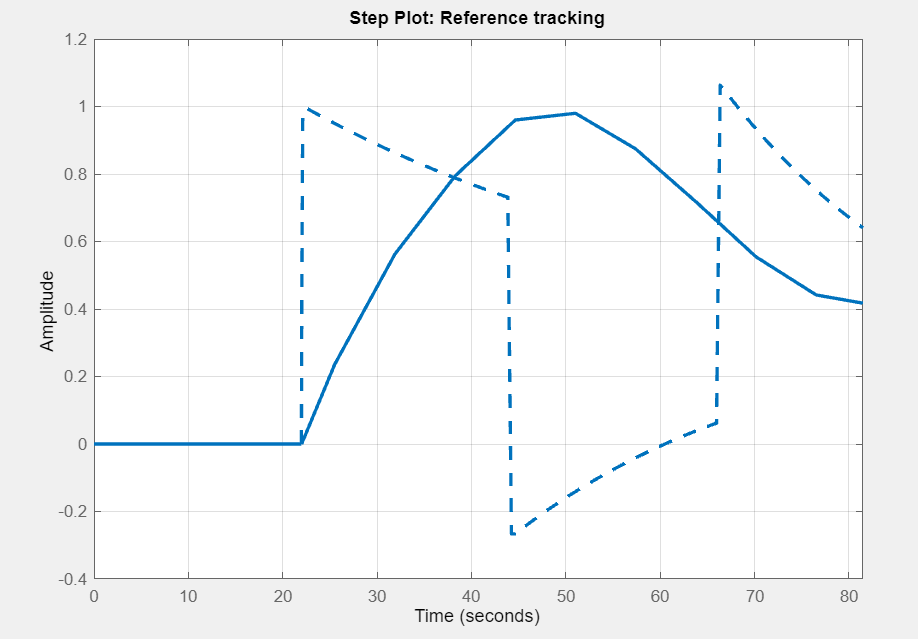

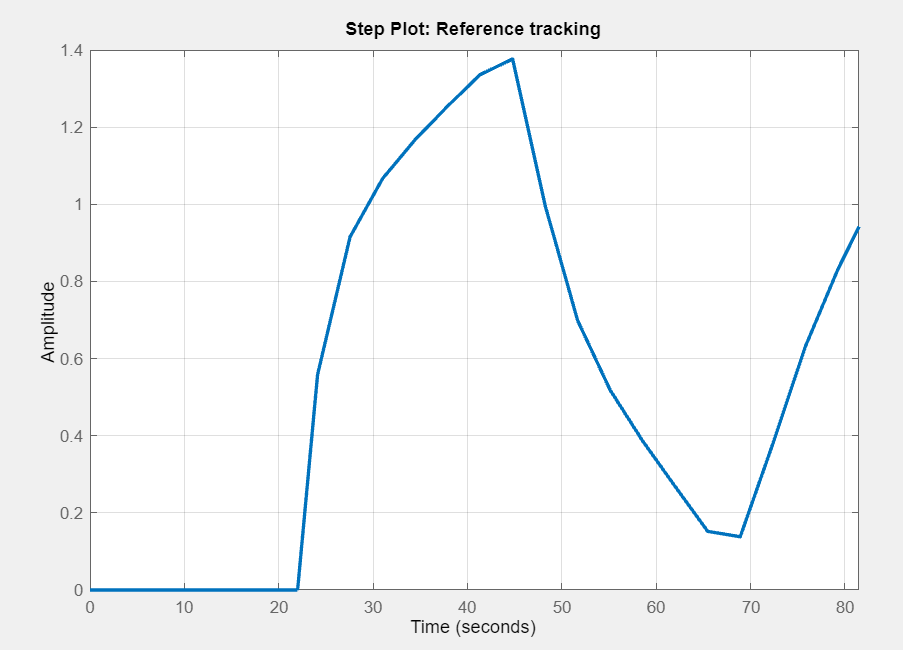

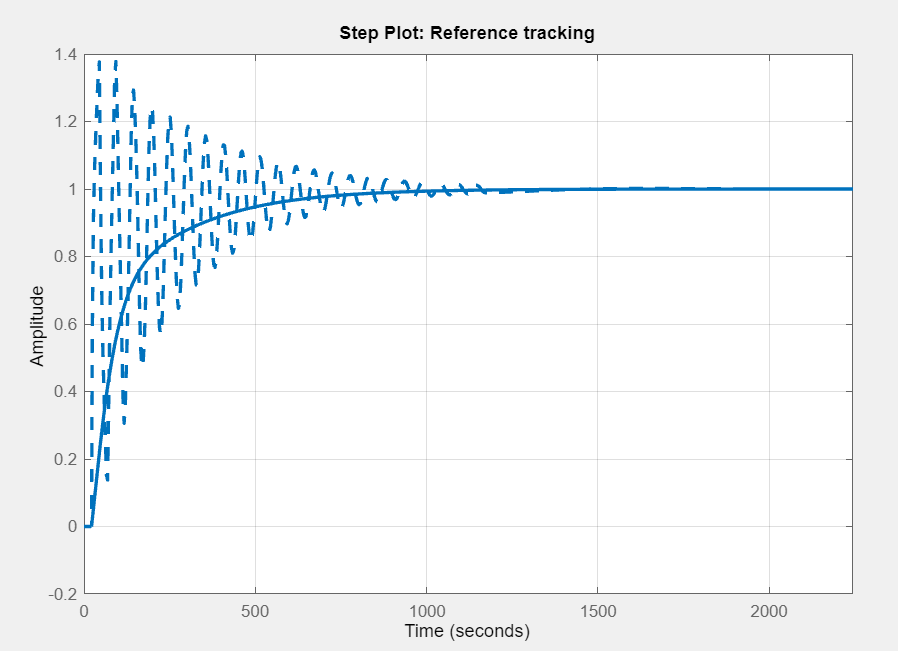

## Wnioski

Pierwsza metoda daje niemalże te same wyniki. W drugiej metodzie oscylacje są bardziej widoczne. Metoda "Autotune" daje najlepsze efekty.